path = EA_dataset{8}.paths(:, 90)
EA_tf_best = 1.45;

EA_dataset{8}.paths


path_EA_dataset_ID = find(EA_dataset{1}.ID2 == path(2));
dataset = {};
dataset{1}.mf = ptr_sols{1}.x(7, end, ptr_sols{1}.converged_i + 1);
dataset{1}.ID1 = path(1);
dataset{1}.ID2 = path(2);
dataset{1}.paths = [path(1); path(2)] 

dataset = 1×1 cell array
    {1×1 struct}


ptr_sols = {};
load_lambert()

coefFilePath = 'C:\Users\thatf\OneDrive\Documents\ASA\PSP-ASA-GTOC12-Problem\LambertSolvers\ivLamV2p41_738416p65617\matlabInterface\lib\ivLamTree_20210202_160219_i2d8.bin'

upToNmaxForStoringDetails = -1


ivLam routines successfully initialized, see log file for details, no limit on number of revolutions
coef path and dll path appear correct, data loaded ok!


Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.108 seconds for 9.264 transfers/s with 100.000% successful


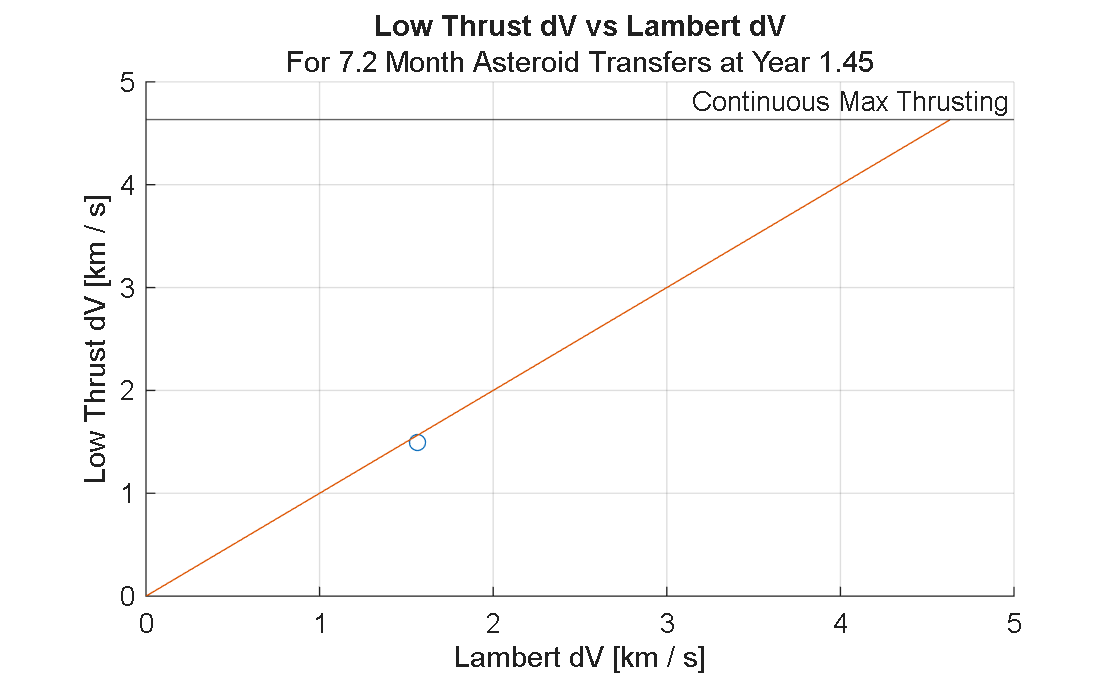

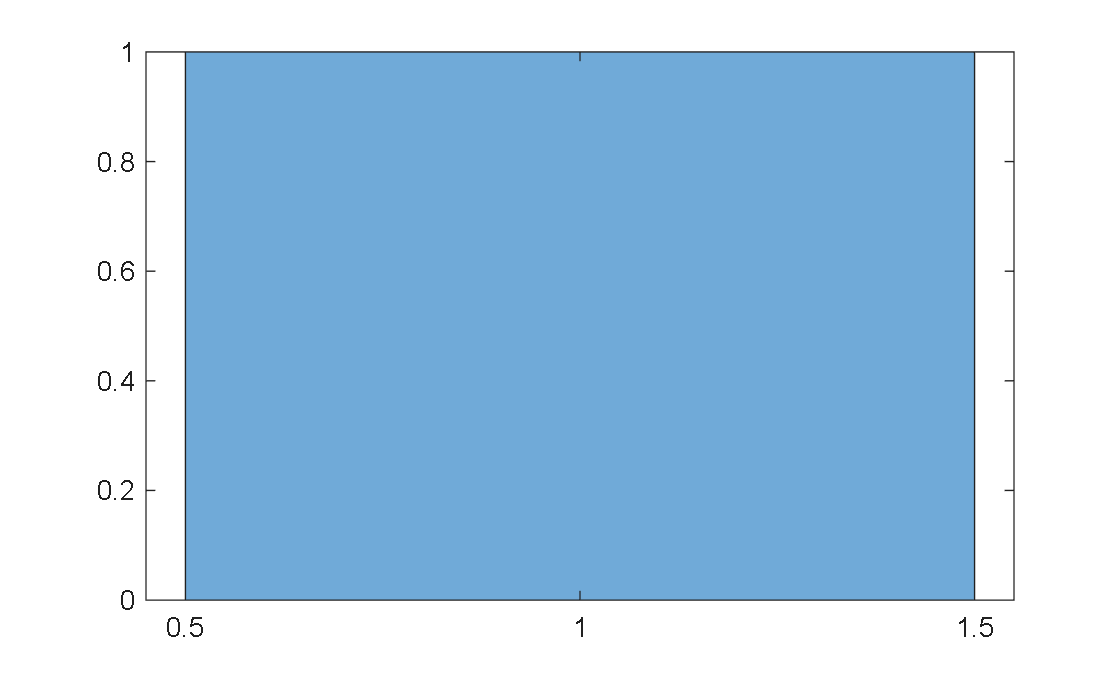

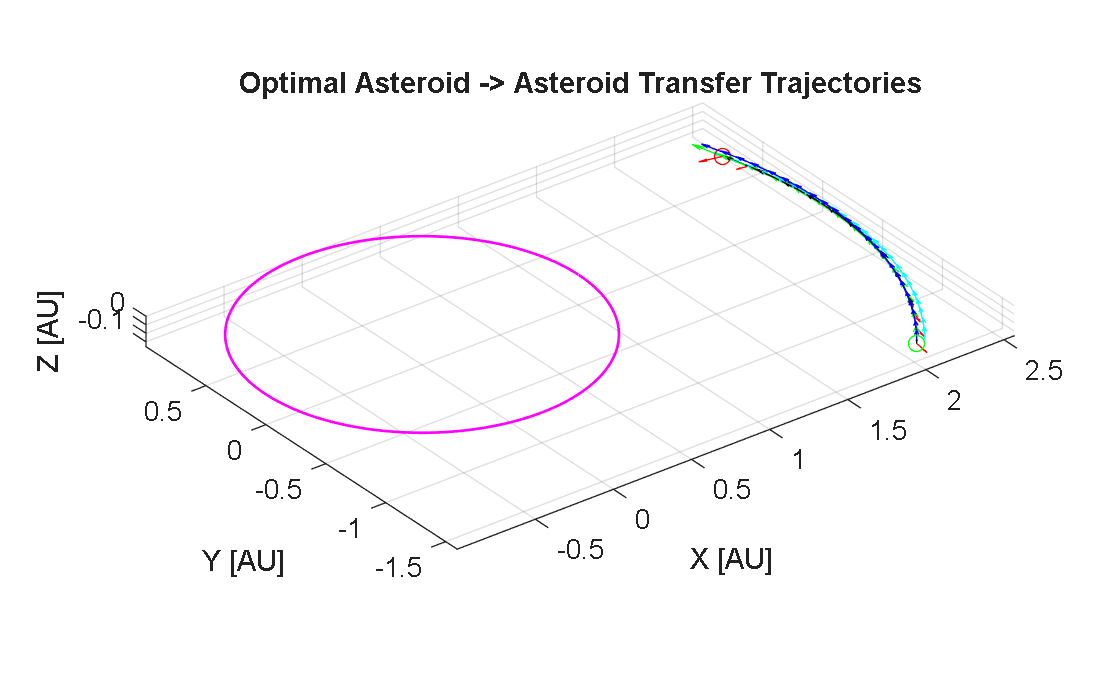

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.032 seconds for 31.085 transfers/s with 100.000% successful


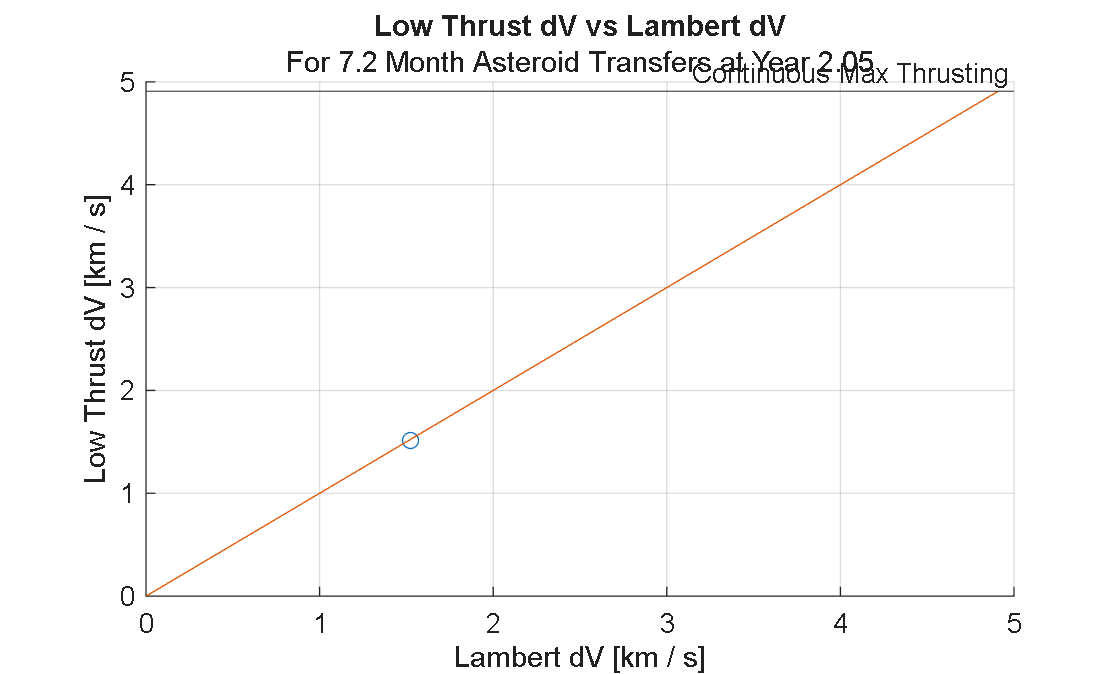

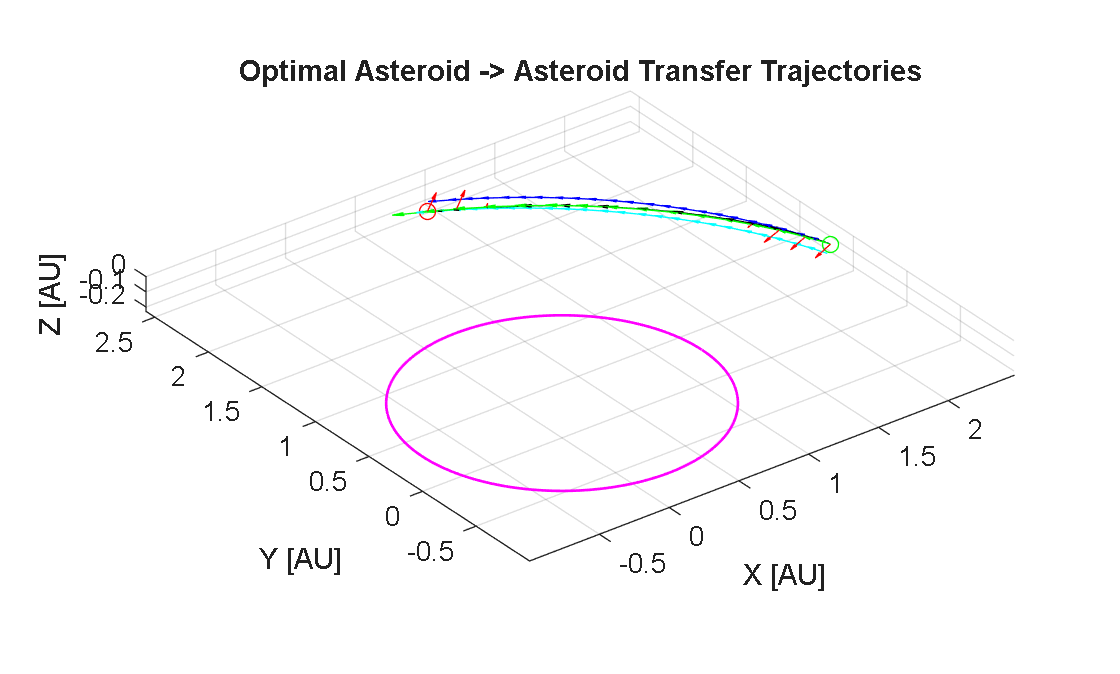

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.036 seconds for 28.157 transfers/s with 100.000% successful


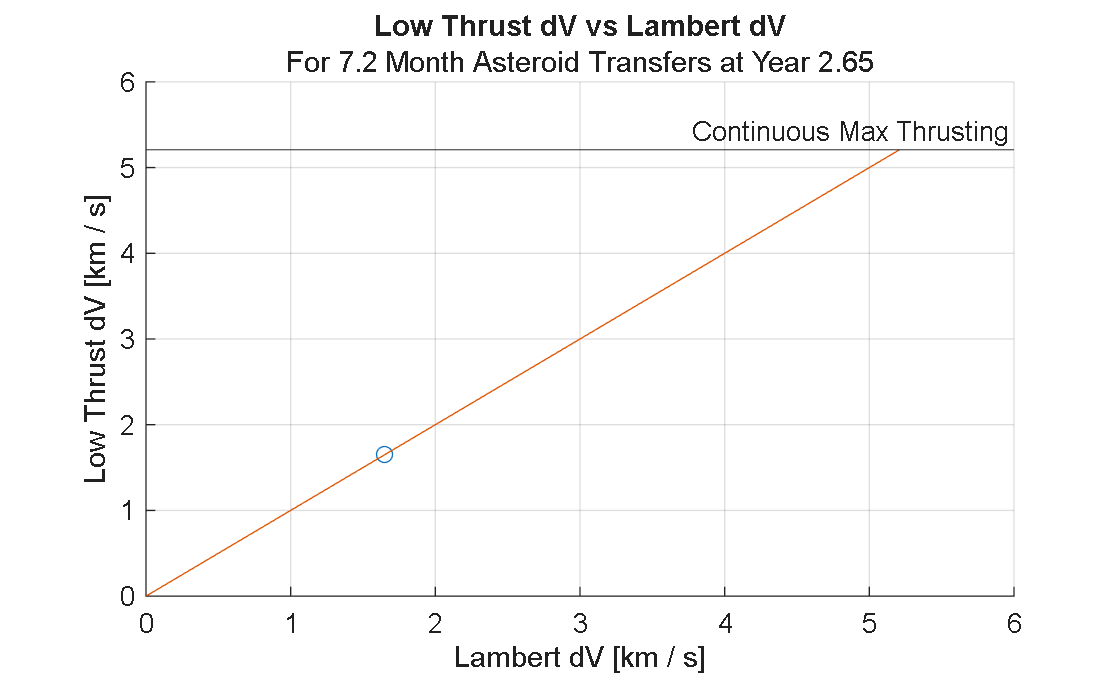

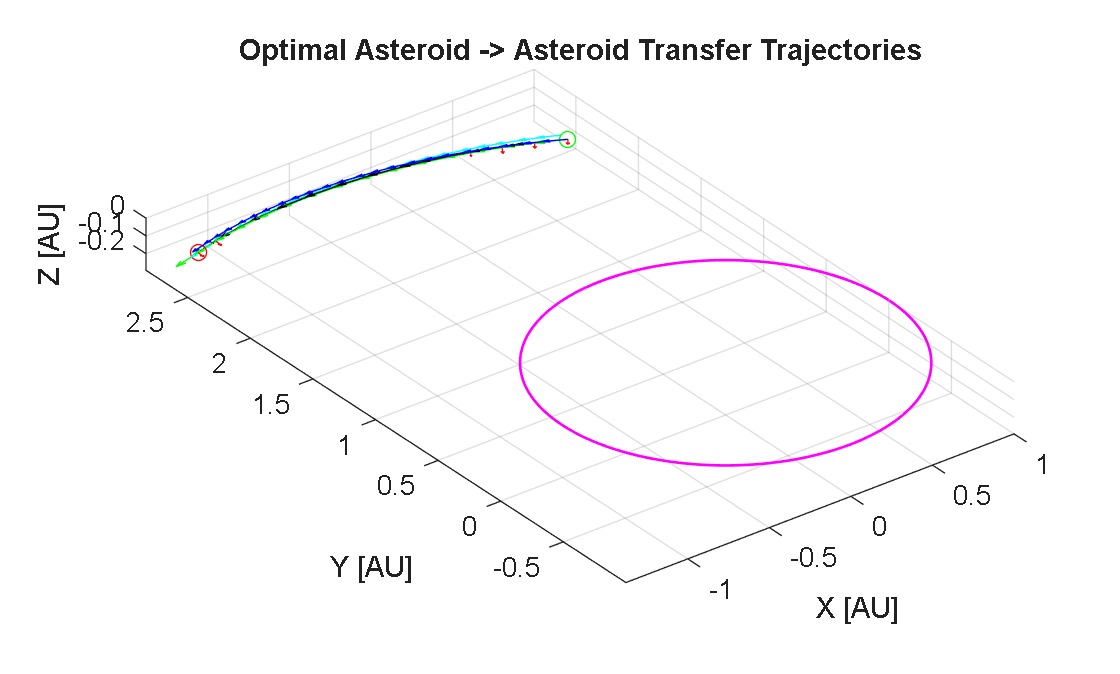

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.044 seconds for 22.696 transfers/s with 100.000% successful


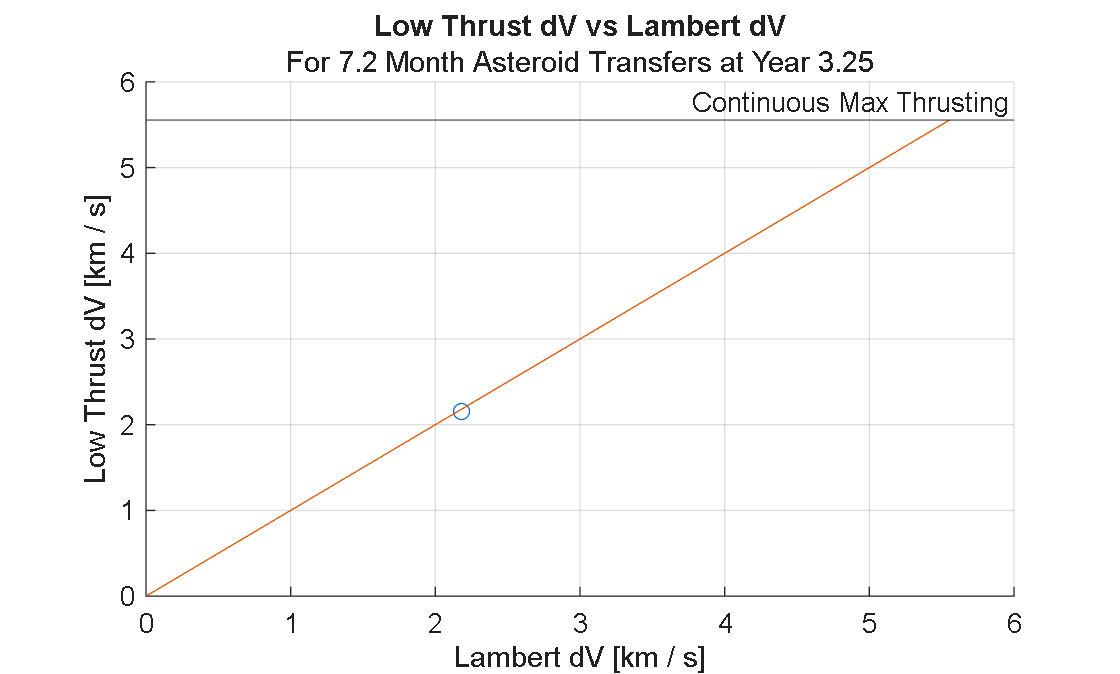

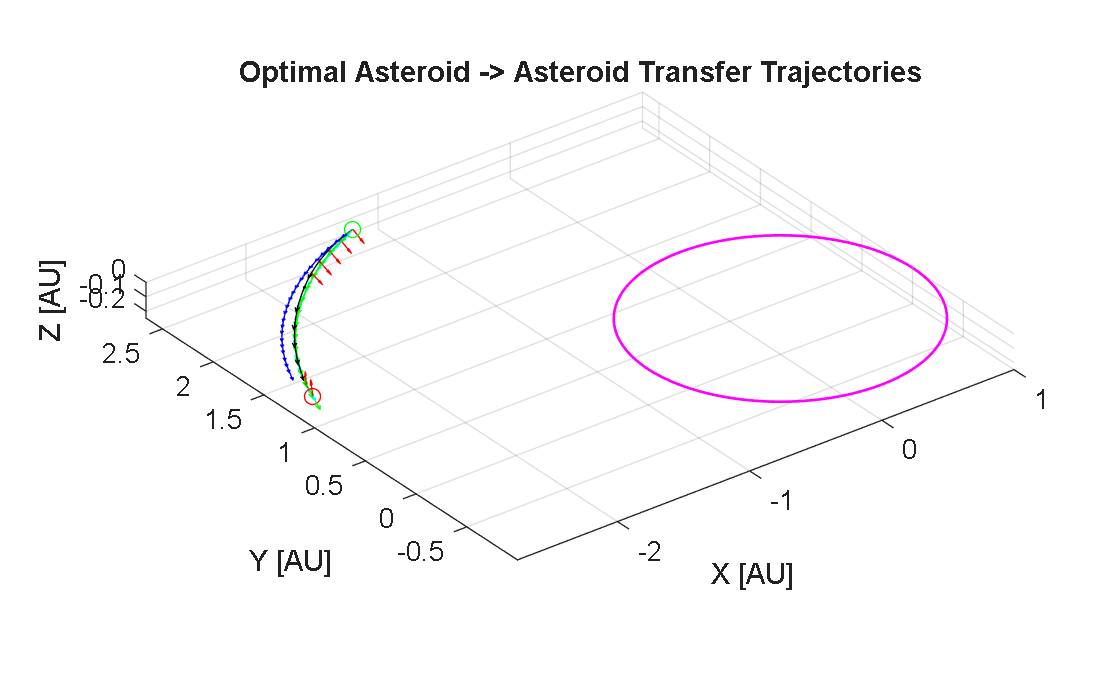

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.036 seconds for 27.920 transfers/s with 100.000% successful


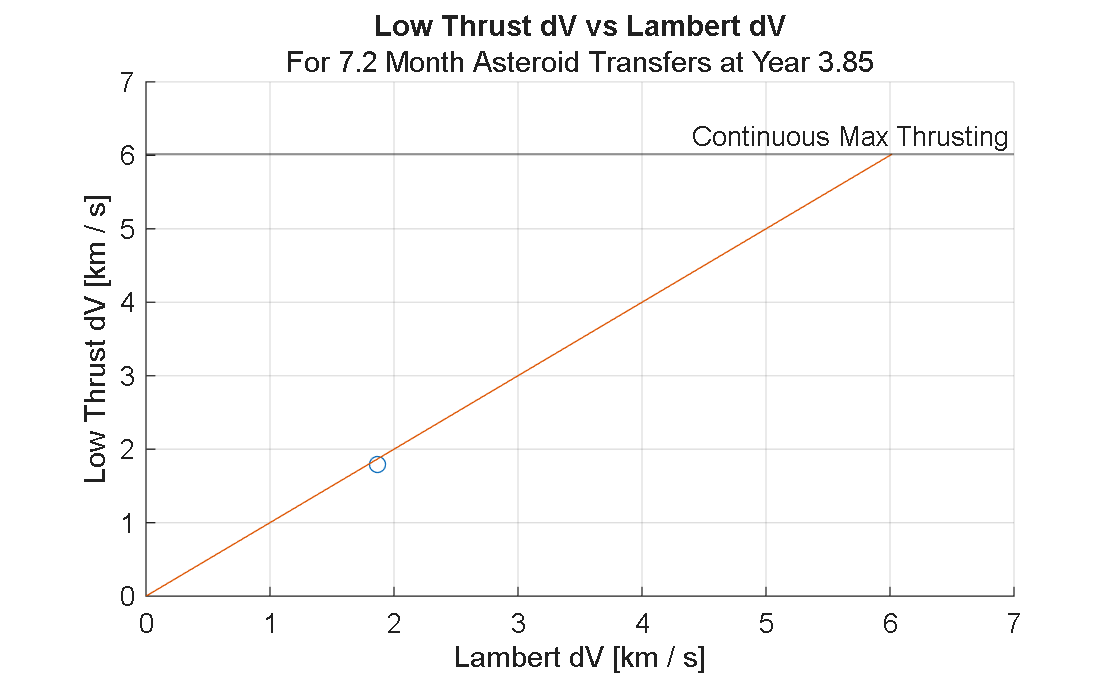

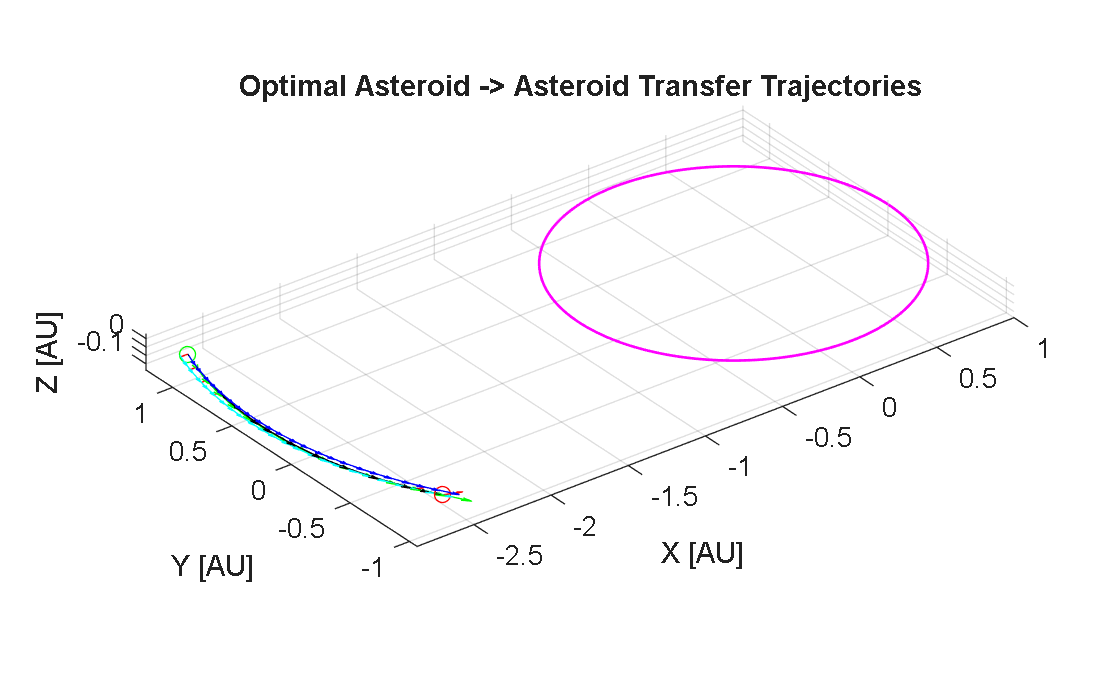

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.039 seconds for 25.574 transfers/s with 100.000% successful


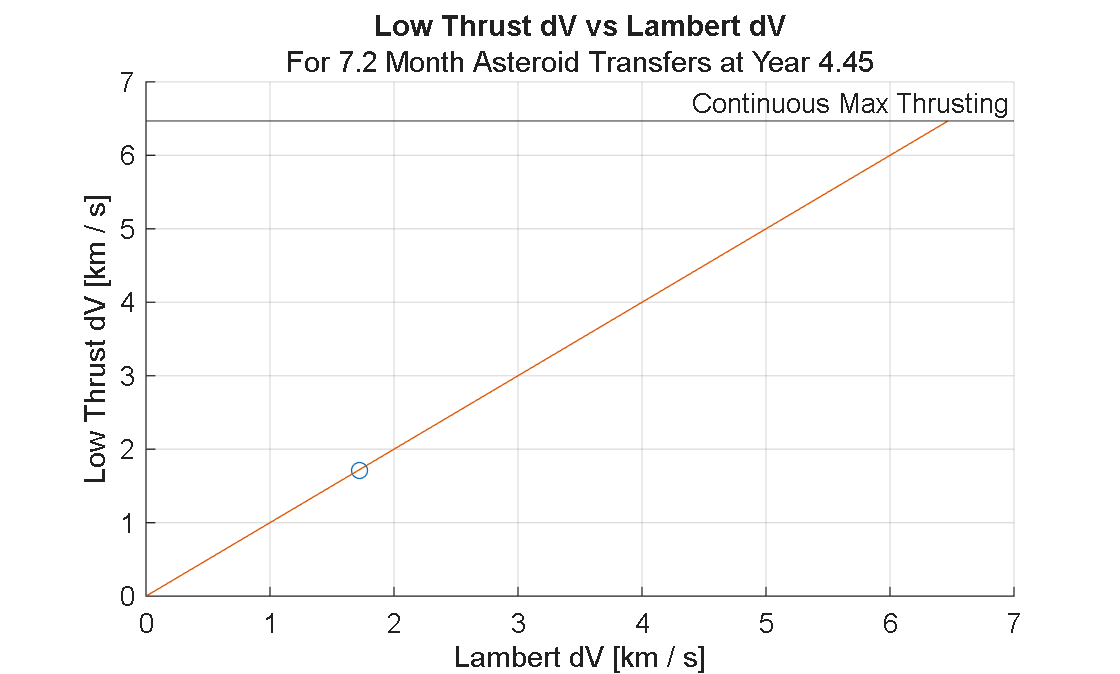

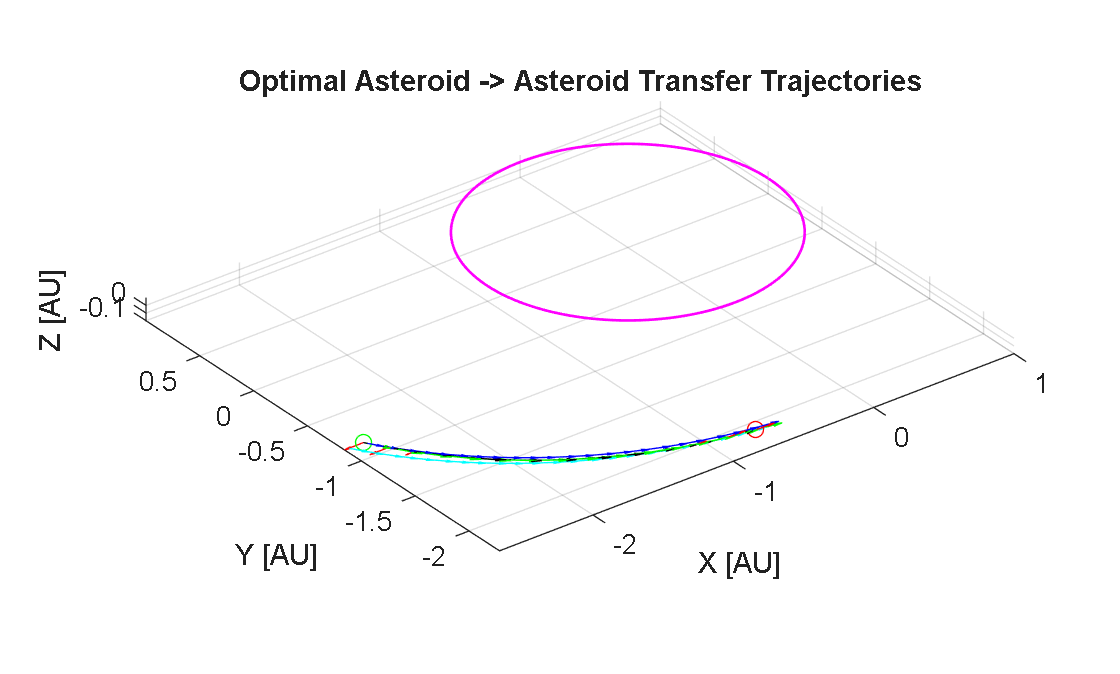

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.036 seconds for 28.088 transfers/s with 100.000% successful


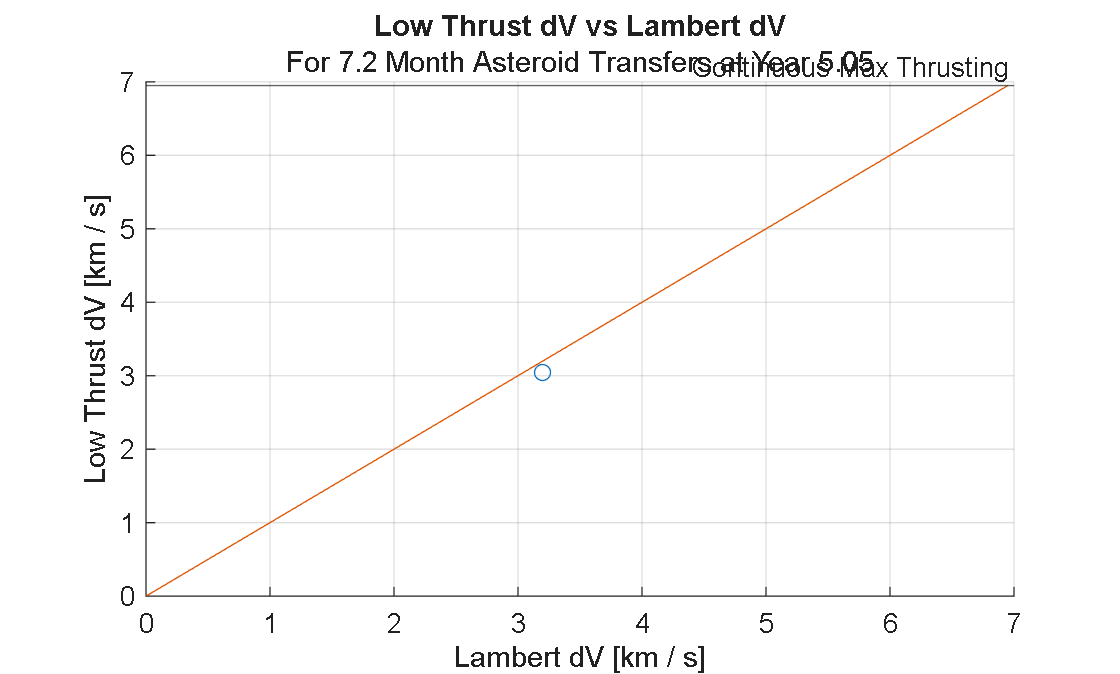

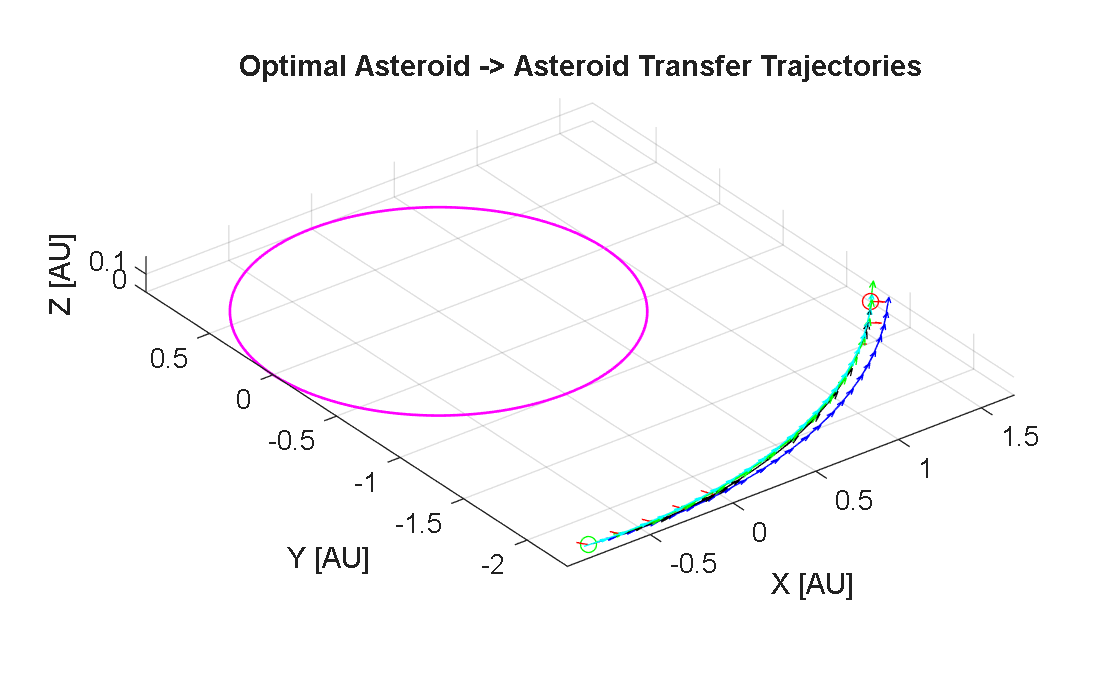

for i = 2 : (numel(path) - 1)
    [dataset{i}, ptr_sols{i}, ~] = Asteroid2Asteroid_lowthrust_batch_func_array(path(i), path(i + 1), dataset{i - 1}.mf - m_miner, (EA_tf_best + ToF_start * (i - 2)), ToF_start, dataset{i - 1}.paths, thrust_frac = 1e10, target_ID1_batch_size = 3000, lambert_multiplier = 1e10, plot = true);
end

## Visualize complete path

ptr_sols

ptr_sols = 1×8 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


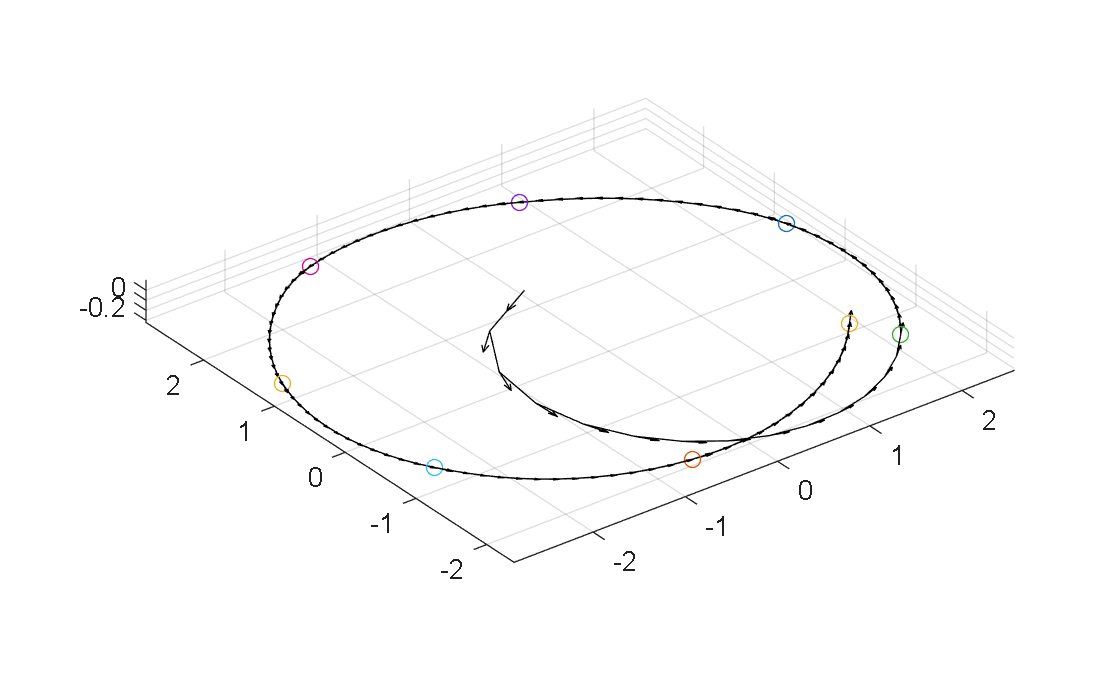

figure
plot_cartesian_orbit(ptr_sols{1}.x(1:3, :, ptr_sols{1}.converged_i + 1)', 'k', 0.4, 1); hold on
for i = 2 : numel(ptr_sols)
    plot_cartesian_orbit(ptr_sols{i}.x(1:3, :)', 'k', 0.4, 1);
    scatter3(ptr_sols{i}.x(1, 1), ptr_sols{i}.x(2, 1), ptr_sols{i}.x(3, 1))
    % [x_kep_0_ast1, M_ast1, E_ast1, nu_ast1, x_keplerian_ast1, x_cartesian_ast1] = get_asteroid(dataset{i}.ID2);
    % t_plot = linspace(0, tf, 100) + (EA_tf + ToF_start * (i - 2)) * year_to_sec / t_star;
    % x_cartesian_ast_plot = zeros([6, numel(t_plot)]);
    % for k = 1:numel(t_plot)
    %     x_cartesian_ast_plot(:, k) = x_cartesian_ast1(t_plot(k));
    % end
    % plot_cartesian_orbit(x_cartesian_ast_plot(1:3, :)', 'b', 0.3, 1)
end
scatter3(ptr_sols{i}.x(1, end), ptr_sols{i}.x(2, end), ptr_sols{i}.x(3, end))
grid on
axis equal

ToFs = 2 * ToF_start * betarnd(20,20,numel(path) - 2,100)'

ToFs =     0.6432    0.6777    0.5572    0.6859    0.6405    0.4957    0.6071
    0.6769    0.6499    0.6489    0.6192    0.5493    0.5748    0.5522
    0.5274    0.6865    0.4742    0.5001    0.5672    0.4892    0.6362
    0.6028    0.5676    0.5589    0.6282    0.6721    0.4419    0.5458
    0.6442    0.6204    0.5283    0.5030    0.6604    0.4482    0.6333
    0.5555    0.5891    0.5275    0.6258    0.5507    0.6376    0.6910
    0.6454    0.7254    0.5582    0.5598    0.4195    0.6605    0.4871
    0.6731    0.6236    0.6402    0.5170    0.7843    0.6316    0.4815
    0.5002    0.4819    0.5609    0.4163    0.4177    0.6260    0.7662
    0.6753    0.5929    0.6094    0.5286    0.5149    0.4477    0.6070
    0.6005    0.6561    0.6469    0.6269    0.7700    0.5578    0.3749
    0.6155    0.6632    0.5063    0.3971    0.4306    0.6326    0.5991
    0.4746    0.6140    0.7520    0.5065    0.6301    0.6172    0.7553
    0.5085    0.6170    0.4594    0.6657    0.6479    0.4083    0.4770

dataset_lambs = {};
for j = 1 : size(ToFs, 1)
    dataset_lamb = {};
    dataset_lamb{1} = dataset{1};
    dataset_lamb{1}.mf_avg = dataset{1}.mf;
    for i = 2 : (numel(path) - 1)
        [dataset_lamb{i}] = Asteroid2Asteroid_lambert_batch_func_array(path(i), path(i + 1), dataset_lamb{i - 1}.mf_avg - m_miner, (EA_tf_best + sum(ToFs(j, 1 : (i - 2)))), ToFs(j, i - 1), dataset{i - 1}.paths, thrust_frac = 1e10, target_ID1_batch_size = 3000, plot = true);
    end
    dataset_lambs{j} = dataset_lamb;
end

Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination batches: 1| Completed: 1
Number of size 3000 combination

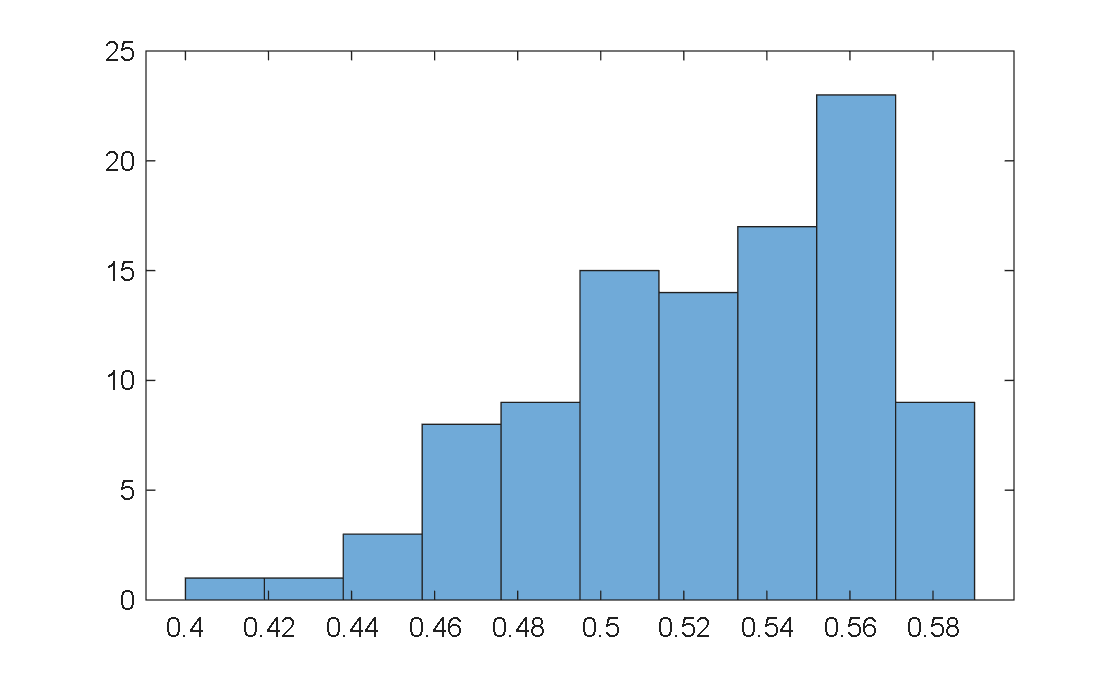

mf_ends = [];
for j = 1 : numel(dataset_lambs)
    mf_ends(j) = dataset_lambs{j}{end}.mf_avg;
end
figure
histogram(mf_ends, 10)

[max_mf, max_mf_i] = max(mf_ends)

max_mf = 0.5877

max_mf_i = 59

dataset{end}.mf

ans = 0.5503

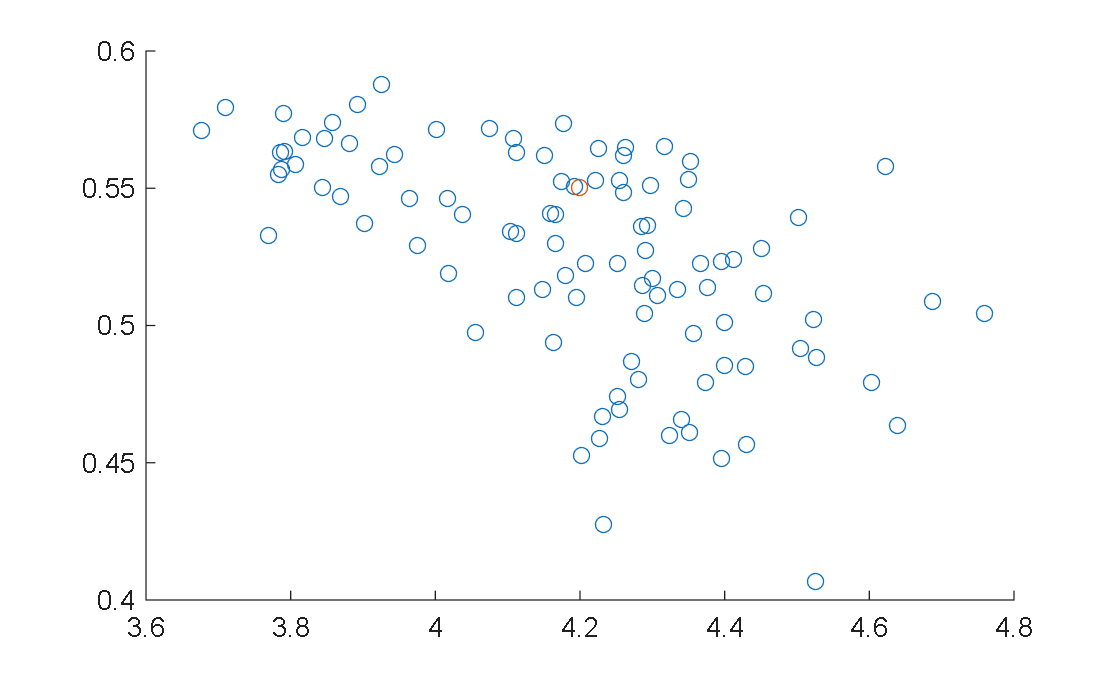

figure
scatter(sum(ToFs(1:end, :)'), mf_ends); hold on
scatter(ToF_start * size(ToFs, 2), dataset{end}.mf)

best_ToFs = ToFs(max_mf_i, :)

best_ToFs =     0.4963    0.5469    0.5403    0.5085    0.5238    0.6849    0.6249


ToF_start * size(ToFs, 2)

ans = 4.2000

dataset_2 = {};
ptr_sols_2 = {};
dataset_2{1} = dataset{1};
ptr_sols_2{1} = ptr_sols{1};
for i = 2 : (numel(path) - 1)
    [dataset_2{i}, ptr_sols_2{i}, ~] = Asteroid2Asteroid_lowthrust_batch_func_array(path(i), path(i + 1), dataset_2{i - 1}.mf - m_miner, (EA_tf_best + sum(best_ToFs(1 : (i - 2)))), best_ToFs(i - 1), dataset_2{i - 1}.paths, thrust_frac = 1e10, target_ID1_batch_size = 3000, lambert_multiplier = 1e10, plot = false);
end

Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.044 seconds for 22.475 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.039 seconds for 25.675 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.033 seconds for 29.893 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.043 seconds for 23.432 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.040 seconds for 24.767 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.038 seconds for 26.298 transfers/s with 100.000% successful
Number of size 3000 combination batches: 1


n_guesses = 1

Completed Batch 1 out of 1, 1
1 transfers in 0.037 seconds for 26.720 transfers/s with 100.000% successful


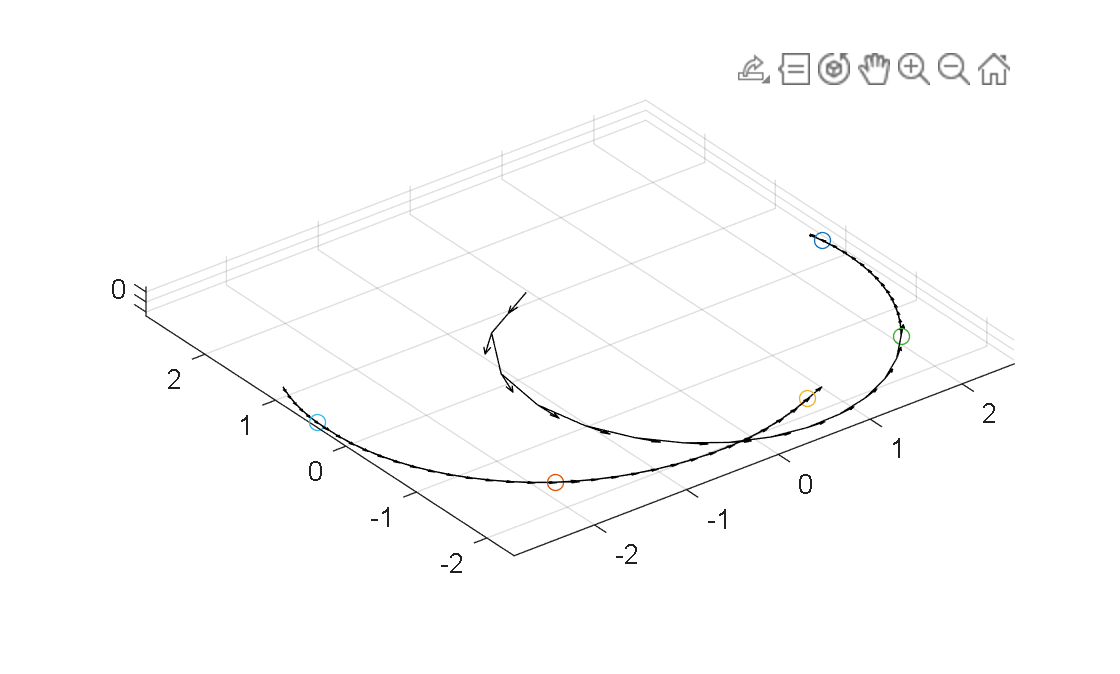

figure
plot_cartesian_orbit(ptr_sols_2{1}.x(1:3, :, ptr_sols_2{1}.converged_i + 1)', 'k', 0.4, 1); hold on
for i = 2 : numel(ptr_sols_2)
    plot_cartesian_orbit(ptr_sols_2{i}.x(1:3, :)', 'k', 0.4, 1);
    scatter3(ptr_sols_2{i}.x(1, 1), ptr_sols_2{i}.x(2, 1), ptr_sols_2{i}.x(3, 1))
    % [x_kep_0_ast1, M_ast1, E_ast1, nu_ast1, x_keplerian_ast1, x_cartesian_ast1] = get_asteroid(dataset{i}.ID2);
    % t_plot = linspace(0, tf, 100) + (EA_tf + ToF_start * (i - 2)) * year_to_sec / t_star;
    % x_cartesian_ast_plot = zeros([6, numel(t_plot)]);
    % for k = 1:numel(t_plot)
    %     x_cartesian_ast_plot(:, k) = x_cartesian_ast1(t_plot(k));
    % end
    % plot_cartesian_orbit(x_cartesian_ast_plot(1:3, :)', 'b', 0.3, 1)
end
scatter3(ptr_sols_2{i}.x(1, end), ptr_sols_2{i}.x(2, end), ptr_sols_2{i}.x(3, end))
grid on
axis equal